# ECEN 611 Homework 5: abc to dqn Transformation 

`Shuxuan Chen | 132006082 | Fall 2024`

*Last updated: Oct 15*

clearvars 
clc 

## Problem 1 

A transformation which is sometimes used in the case of synchronous machines, is one where fds leads fqs by 90 degrees with ω=ωr. 

### (a) Express the transformation. 

abc to dq transformation using rotor reference frame 

% [fds, fqs] = [T](fas, fbs, fcs)

### (b) Using this transformation, write the voltage equations for a 3-phase inductive circuit.

% vas = ias * rs + Las * dias/dt 
% vbs = ibs * rs + Lbs * dibs/dt 
% vcs = ics * rs + Lcs * dics/dt 
% refer to my efforts in summer 

## Problem 2 

For the following reactor find the dqn equivalent circuit in the stationary reference frame. Neglect the iron reluctances in the horizontal paths. Do not neglect the iron reluctances in the vertical paths.

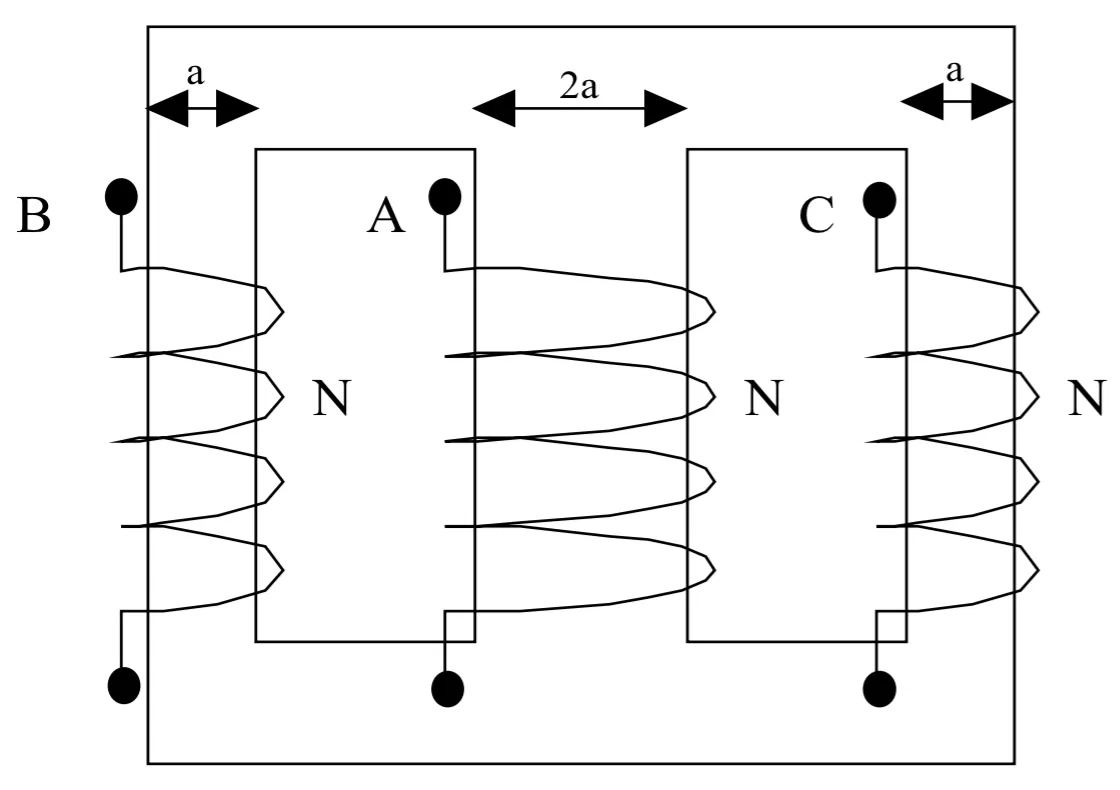

% only consider phase A 
% use minimum number of variables 
% what does N mean?
syms i_A i_B i_C
syms i_dot_A i_dot_B i_dot_C

syms r_A r_B r_C

syms L_AA L_AB L_AC 
syms L_BA L_BB L_BC
syms L_CA L_CB L_CC
% L_AA can be later substituted for magnetizing + leakage 

syms p 
syms lambda_A lambda_B lambda_C
syms lambda_dot_A lambda_dot_B lambda_dot_C

resistances = [r_A; r_B; r_C];

currents_a_b_c = [i_A; i_B; i_C];
currents_dot_a_b_c = [i_dot_A; i_dot_B; i_dot_C];

inductances = ...
[
    L_AA L_AB L_AC; 
    L_BA L_BB L_BC;
    L_CA L_CB L_CC
];

fluxLinkages = [lambda_A; lambda_B; lambda_C];
fluxLinkages_dot = [lambda_dot_A; lambda_dot_B; lambda_dot_C];

voltage_a_b_c = currents_a_b_c .* resistances + fluxLinkages_dot;
disp('Voltage equations in abc are: ')

Voltage equations in abc are: 


disp(voltage_a_b_c)

$$\left(\begin{array}{c} {\dot{\lambda }}_{A}+i_{A}\,r_{A}\\ {\dot{\lambda }}_{B}+i_{B}\,r_{B}\\ {\dot{\lambda }}_{C}+i_{C}\,r_{C} \end{array}\right)$$

fluxLinkages_dot_a_b_c = inductances * currents_dot_a_b_c;
disp('Flux linkage equations in abc are: ') 

Flux linkage equations in abc are: 


disp(fluxLinkages_dot_a_b_c) % ignore bars on top of symbols; they make no difference 

$$\left(\begin{array}{c} L_{\mathrm{AA}}\,{\dot{i}}_{A}+L_{\mathrm{AB}}\,{\dot{i}}_{B}+L_{\mathrm{AC}}\,{\dot{i}}_{C}\\ L_{\mathrm{BA}}\,{\dot{i}}_{A}+L_{\mathrm{BB}}\,{\dot{i}}_{B}+L_{\mathrm{BC}}\,{\dot{i}}_{C}\\ L_{\mathrm{CA}}\,{\dot{i}}_{A}+L_{\mathrm{CB}}\,{\dot{i}}_{B}+L_{\mathrm{CC}}\,{\dot{i}}_{C} \end{array}\right)$$

voltage_a_b_c = subs( voltage_a_b_c, fluxLinkages_dot, fluxLinkages_dot_a_b_c );
disp('Voltage equations substituted by flux linkage equations in abc are: ')

Voltage equations substituted by flux linkage equations in abc are: 


disp(voltage_a_b_c)

$$\left(\begin{array}{c} L_{\mathrm{AA}}\,{\dot{i}}_{A}+L_{\mathrm{AB}}\,{\dot{i}}_{B}+L_{\mathrm{AC}}\,{\dot{i}}_{C}+i_{A}\,r_{A}\\ L_{\mathrm{BA}}\,{\dot{i}}_{A}+L_{\mathrm{BB}}\,{\dot{i}}_{B}+L_{\mathrm{BC}}\,{\dot{i}}_{C}+i_{B}\,r_{B}\\ L_{\mathrm{CA}}\,{\dot{i}}_{A}+L_{\mathrm{CB}}\,{\dot{i}}_{B}+L_{\mathrm{CC}}\,{\dot{i}}_{C}+i_{C}\,r_{C} \end{array}\right)$$

% Solve for the matrix form
syms v_A v_B v_C
voltages = [v_A; v_B; v_C];

% symvar(voltage_eqns_abc == voltages)

pCurrents = p*currents_a_b_c;

[A, b] = equationsToMatrix(voltage_a_b_c == voltages, currents_dot_a_b_c);
disp('Matrix form of the system:');

Matrix form of the system:


disp(A);

$$\left(\begin{array}{ccc} L_{\mathrm{AA}} & L_{\mathrm{AB}} & L_{\mathrm{AC}}\\ L_{\mathrm{BA}} & L_{\mathrm{BB}} & L_{\mathrm{BC}}\\ L_{\mathrm{CA}} & L_{\mathrm{CB}} & L_{\mathrm{CC}} \end{array}\right)$$

disp(b);

$$\left(\begin{array}{c} v_{A}-i_{A}\,r_{A}\\ v_{B}-i_{B}\,r_{B}\\ v_{C}-i_{C}\,r_{C} \end{array}\right)$$

### abc to dqn Transformation Matrix 

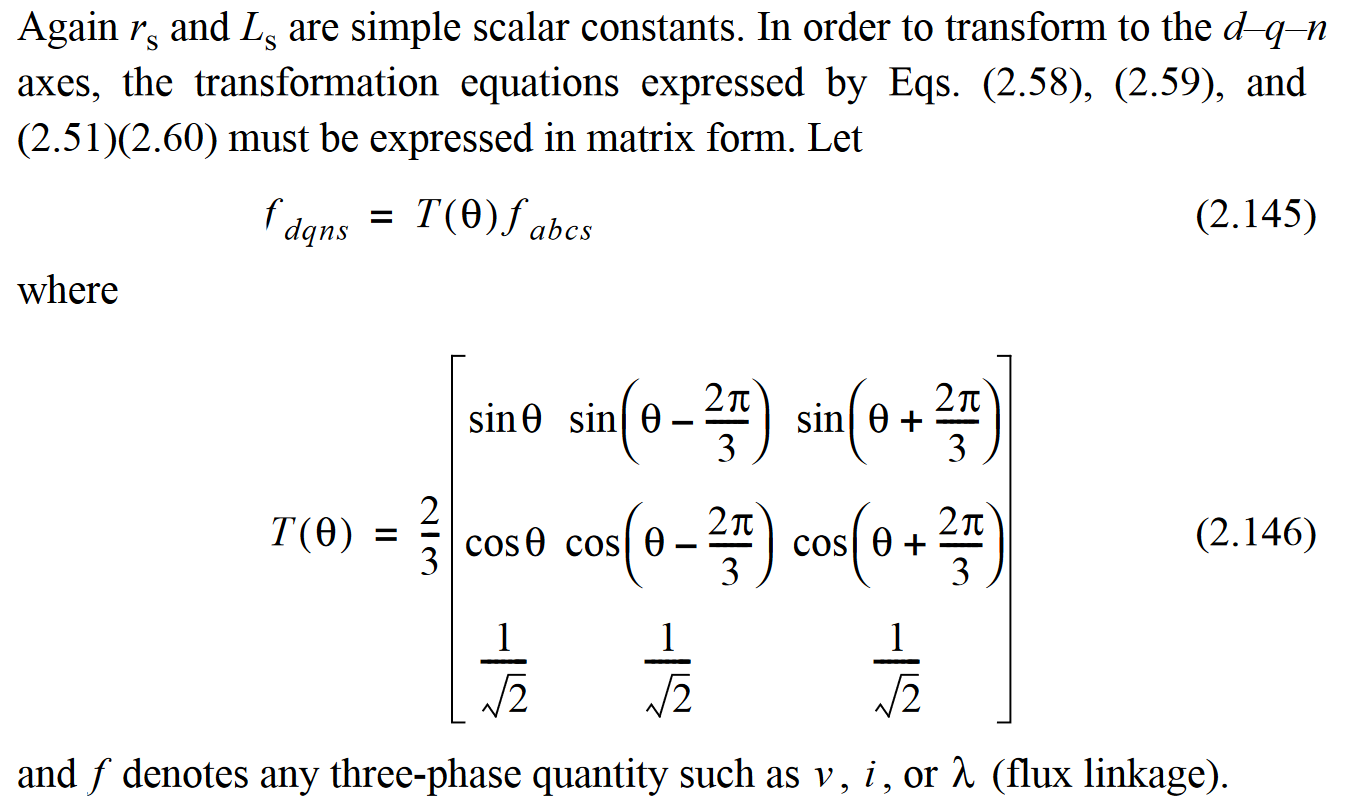

syms T_abc2dq(theta) 

phi = 2*pi/3;
T_abc2dq(theta) = 2/3 * [ ...
    sin(theta) sin(theta-phi) sin(theta+phi);
    cos(theta) cos(theta-phi) cos(theta+phi);
     1/sqrt(2)      1/sqrt(2)      1/sqrt(2)
];
disp('abc to dqn Transformation Matrix: ')

abc to dqn Transformation Matrix: 


disp(T_abc2dq(theta))

$$\left(\begin{array}{ccc} \frac{2\,\sin\left(\theta \right)}{3} & \frac{2\,\sin\left(\theta -\frac{2\,\pi }{3}\right)}{3} & \frac{2\,\sin\left(\theta +\frac{2\,\pi }{3}\right)}{3}\\ \frac{2\,\cos\left(\theta \right)}{3} & \frac{2\,\cos\left(\theta -\frac{2\,\pi }{3}\right)}{3} & \frac{2\,\cos\left(\theta +\frac{2\,\pi }{3}\right)}{3}\\ \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} \end{array}\right)$$


U = sym(ones(3,3))

$$U = \left(\begin{array}{ccc} 1 & 1 & 1\\ 1 & 1 & 1\\ 1 & 1 & 1 \end{array}\right)$$

T_abc2dq(0) * U / T_abc2dq(0)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 3 \end{array}\right)$$


% Alternatives
% T_abc2dq(0)^(-1) = inv(T_abc2dq(0))
% U * inv(T_abc2dq(0)) = U / T_abc2dq(0)

### abc to dqn to Transformation 

% theta = 0: stationary reference frame 
% theta = ω: arbitrary reference frame 
% theta = ωr: rotor reference frame 
% theta = ωe: synchronous reference frame 

% voltage_eqns_dqn = T_abc2dq(0) * voltage_a_b_c;
% disp('Voltage equations in stationary dqn are: ')
% disp(voltage_eqns_dqn)

### Parameterized dqn Voltage Equations 

syms r_s 
vars_resistance = [r_A r_B r_C];
VARS_resistance = [r_s r_s r_s];

syms i_abc i_dot_abc [3 1] matrix 
syms L_matrix [3 3] matrix 
voltage_abc = r_s * i_abc + L_matrix * i_dot_abc;

disp('Voltage equation in single-line abc: ')

Voltage equation in single-line abc: 


disp(voltage_abc)

$$L_{\mathrm{matrix}}\,{\dot{i}}_{\mathrm{abc}}+r_{s}\,i_{\mathrm{abc}}$$


vv = subs(voltage_abc, ...
    {L_matrix, i_abc, i_dot_abc}, ...
    {inductances, currents_a_b_c, currents_dot_a_b_c})

$$vv = \left(\begin{array}{c} L_{\mathrm{AA}}\,{\dot{i}}_{A}+L_{\mathrm{AB}}\,{\dot{i}}_{B}+L_{\mathrm{AC}}\,{\dot{i}}_{C}\\ L_{\mathrm{BA}}\,{\dot{i}}_{A}+L_{\mathrm{BB}}\,{\dot{i}}_{B}+L_{\mathrm{BC}}\,{\dot{i}}_{C}\\ L_{\mathrm{CA}}\,{\dot{i}}_{A}+L_{\mathrm{CB}}\,{\dot{i}}_{B}+L_{\mathrm{CC}}\,{\dot{i}}_{C} \end{array}\right)+r_{s}\,\left(\begin{array}{c} i_{A}\\ i_{B}\\ i_{C} \end{array}\right)$$

% % Check sizes
% disp(size(i_abc));
% disp(size(i_dot_abc));
% disp(size(currents_a_b_c));
% disp(size(currents_dot_a_b_c));
% 
% % Ensure replacement elements match in size
% if isequal(size(i_abc), size(currents_a_b_c)) && isequal(size(i_dot_abc), size(currents_dot_a_b_c))
%     voltage_abc_substituted = subs(voltage_abc, [i_abc, i_dot_abc], [currents_a_b_c, currents_dot_a_b_c]);
%     disp('Substituted Voltage Equation:');
%     disp(voltage_abc_substituted);
% else
%     error('Replacement variables do not match in size. Please ensure they are compatible.');
% end




% syms L_m 
% vars_Lxx = [L_AA L_BB L_CC];
% VARS_LXX = [L_m L_m L_m];
% 
% % need to figure out LCB, LBC, LAB, LBA, LAC, LCA
% % better represent them by L_m 
% 
% vars_Lxy = []; 

## Problem 3 

Assume the steady state abc variables are of the form where Fa, Fb, and Fc are unequal constants. Show that this unbalanced set of abc variables forms 2-phase balanced sets of qs and ds variables in the arbitrary reference frame with the arguments of (ωet-θ) and (ωet+θ). Note the form of the qs and ds variables when ω=ωe and ω=−ωe.

syms F_a F_b F_c   real positive 
syms omega_e omega real positive 
syms t             real positive 

aa = exp(1i*2*pi/3);

amplitude = [F_a, F_b, F_c];

[Fas, Fbs, Fcs] = get_fa_fb_fc( sqrt(2)*[F_a, F_b, F_c], omega_e )

$$Fas = \sqrt{2}\,F_{a}\,\cos\left(\omega_{e}\,t\right)$$

$$Fbs = \sqrt{2}\,F_{b}\,\cos\left(\frac{2\,\pi }{3}-\omega_{e}\,t\right)$$

$$Fcs = \sqrt{2}\,F_{c}\,\cos\left(\frac{2\,\pi }{3}+\omega_{e}\,t\right)$$


get_fabc = @(fa, fb, fc) fa + aa * fb + aa^2 * fc; 
Fabcs_s = get_fabc( Fas, Fbs, Fcs )

$$Fabcs\_s = \sqrt{2}\,F_{a}\,\cos\left(\omega_{e}\,t\right)+\sqrt{2}\,F_{b}\,\cos\left(\frac{2\,\pi }{3}-\omega_{e}\,t\right)\,\left(-\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)-\sqrt{2}\,F_{c}\,\cos\left(\frac{2\,\pi }{3}+\omega_{e}\,t\right)\,\left(\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)$$


% Option 1:
% % Define the function to return two outputs
% get_fq_fd = @(fqd) deal(real(fqd), -imag(fqd));
% 
% % Call the function with two outputs
% [Fqs, Fds] = get_fq_fd(Fabcs_s)

% Define the function to return a single 1x2 array
get_fq_fd = @(fqd) [real(fqd), -imag(fqd)];

% Call the function and index the outputs
Fqds = get_fq_fd( Fabcs_s * exp(-1i*omega*t) );
Fqs = Fqds(1);
Fds = Fqds(2);

It is seen that unbalanced set of abc variables forms 2-phase balanced sets of qs and ds variables in the arbitrary reference frame with the arguments of (ωe-ω)t and (ωe+ω)t

Fqs = rewrite(simplify(expand(Fqs)),"exp");
Fds = rewrite(simplify(expand(Fds)),"exp");

disp('Fqs: ')

Fqs: 


disp(Fqs)

$$\sqrt{2}\,\left(\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}-\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}-\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}-\frac{\sqrt{3}\,F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}+\frac{\sqrt{3}\,F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}\right)$$


disp('Fds: ')

Fds: 


disp(Fds)

$$\sqrt{2}\,\left(\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}-\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}-\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}+\frac{\sqrt{3}\,F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}-\frac{\sqrt{3}\,F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}\right)$$

When ω=ωe and ω=−ωe

omegas = [omega_e -omega_e];

for i = 1:length(omegas)
    thisOmega = omegas(i);
    
    disp(['When omega = ', char(thisOmega), ':'])
    disp('Fqs: ')
    disp(simplify(subs(Fqs, omega, thisOmega)));

    disp('Fqs: ')
    disp(simplify(subs(Fds, omega, thisOmega)));
end

When omega = omega_e:


Fqs: 


$$\frac{\sqrt{2}\,{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\left(2\,F_{a}-F_{b}-F_{c}-\sqrt{3}\,F_{b}\,\mathrm{i}+\sqrt{3}\,F_{c}\,\mathrm{i}+4\,F_{a}\,{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}+2\,F_{a}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}+4\,F_{b}\,{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}-F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}+4\,F_{c}\,{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}-F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}+\sqrt{3}\,F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}-\sqrt{3}\,F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}\right)}{8}$$

Fqs: 


$$\frac{\sqrt{2}\,{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\left(2\,F_{a}\,\mathrm{i}-F_{b}\,\mathrm{i}-F_{c}\,\mathrm{i}+\sqrt{3}\,F_{b}-\sqrt{3}\,F_{c}-2\,F_{a}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}+F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}+F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}+\sqrt{3}\,F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}-\sqrt{3}\,F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\right)}{8}$$

When omega = -omega_e:


Fqs: 


$$\sqrt{2}\,\left(\frac{F_{a}}{2}-\frac{F_{b}}{4}-\frac{F_{c}}{4}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}}{2}\right)}{2}\right)$$

Fqs: 


$$-\sqrt{2}\,\left(\frac{\sqrt{3}\,F_{c}}{4}-\frac{\sqrt{3}\,F_{b}}{4}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}\right)$$

function [fa, fb, fc] = get_fa_fb_fc(amplitude, frequency)
    syms t real positive 
    fa = amplitude(1) * cos( frequency * t );
    fb = amplitude(2) * cos( frequency * t - 2*pi/3 );
    fc = amplitude(3) * cos( frequency * t + 2*pi/3 );
end 

## Syntax Review

segments = {'A', 'B', 'C'};
otherLegs = setdiff(segments, 'A') % `seg1` could be 'A', 'B', or 'C'

otherLegs = 1×2 cell array
    {'B'}    {'C'}



% strcmp